[fseries] = fourier_series(5, 2*pi);

The Fourier Series is : 


$$0.02546479089\,\cos\left(5.0\,x\right)-0.25\,\sin\left(4.0\,x\right)-0.5\,\sin\left(2.0\,x\right)-0.4726760455\,\sin\left(5.0\,x\right)+0.07073553026\,\cos\left(3.0\,x\right)-0.7877934092\,\sin\left(3.0\,x\right)+0.6366197724\,\cos\left(x\right)-2.363380228\,\sin\left(x\right)+2.85619449$$

fplot(fseries, [0 6*pi])
hold on;
f = @(x) 1.*(0 <= x & x < pi) + x.*( pi <= x & x <= 2*pi)

f = function_handle with value:
    @(x)1.*(0<=x&x<pi)+x.*(pi<=x&x<=2*pi)


x = linspace(0, 2*pi, 100);
y = f(x);
ry = repmat(y, 1, 3);
rx = linspace(0, 6*pi, length(ry))

rx =          0    0.0630    0.1261    0.1891    0.2522    0.3152    0.3783    0.4413    0.5043    0.5674    0.6304    0.6935    0.7565    0.8195    0.8826    0.9456    1.0087    1.0717    1.1348    1.1978    1.2608    1.3239    1.3869    1.4500    1.5130    1.5760    1.6391    1.7021    1.7652    1.8282    1.8913    1.9543    2.0173    2.0804    2.1434    2.2065    2.2695    2.3326    2.3956    2.4586    2.5217    2.5847    2.6478    2.7108    2.7738    2.8369    2.8999    2.9630    3.0260    3.0891


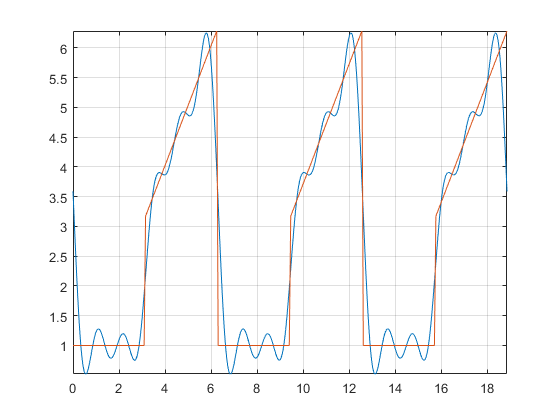

plot(rx, ry);
grid on;
hold off;